# Generate a List of Figures in a Report

Create a list of figures as an `mlreportgen.dom.LOF` object. To include figures in the list:

- Create captions for the figures as `mlreportgen.dom.Paragraph` objects.

- Associate the `Paragraph` objects with a numbering stream that has the name `figure`.

Import the DOM package so that you do not have to use long, fully qualified class names.

import mlreportgen.dom.*

Create a report.

d = Document("DOM Report with List of Figures","docx");

Create an `LOF` object and append it to the report.

LOFObj = LOF();
append(d,LOFObj);
append(d,PageBreak);

Include an image (figure) in the report.

append(d,Image('peppers.png'));

Create a paragraph for the figure caption. 

p1 = Paragraph("Figure ");

Create an automatic numbering stream with the name `figure` and associate it with the paragraph. 

append(p1,AutoNumber("figure"));

Increment the counter for the numbering stream.

p1.Style = {CounterInc("figure"),WhiteSpace("preserve")};

Append the rest of the caption text to the paragraph and append the paragraph to the report.

append(p1,".");
append(p1," Peppers");
append(d,p1);

Include another image in the report and create a caption for the figure. Associate the caption with the figure numbering stream. 

append(d,Image("b747.jpg"));
p2 = Paragraph("Figure ");
append(p2,AutoNumber("figure"));
p2.Style = {CounterInc("figure"),WhiteSpace("preserve")};

Append the rest of the caption text to the paragraph and append the paragraph to the report.

append(p2,".");
append(p2," Airplane");
append(d,p2);

Close and view the report.

close(d);
rptview(d);

Here is the list of figures in the generated report:

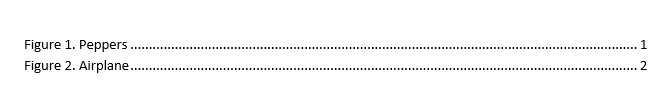

*Copyright 2020 The MathWorks, Inc.*